# Project 1 Design Question (W2025)

## Introduction

This is the one of the analysis problems for the first project. This is an somewhat open-ended question that is unique to each student. You will find the question in this LiveScript file. You must add content to this file and provide complete answers to the questions. You will need to provide the math to do the calculations necessary to find your answers, but for full credit you must also provide accompanying text to explain what you are doing. 

### Solution restrictions: 

- You may use any of the base functions in Matlab, the symbolic math toolbox, as well as simple functions that provide principal axis rotations (be sure you know the sense of the rotations, though). You may not use any other scripts or functions, particularly if they come from other people. 

- Do not use any random number generation in you solutions; this will disturb the question generation functions.

- If for any reason the random generators produce something that is impossible to solve, add one to your student number and try running the script again (make a note of the problem you had) 

- For full credit, the code you write must run without errors and produce the correct answer.

- Do not modify the instructor-provided sections in any way. You may take as much space as you need to complete the questions, but leave the actual question text intact.

(Please type your name and student number here.)

%Please enter you student number here as well. 
student_number = 1234568;
my_seed = rng(student_number);

## Problem Description

With the recent success of the Mars Perseverance  Rover and the Ingenuity helicopter, engineers are seriously considering the role that powered flight can play in the exploration of Mars. Although with the current mission, Ingenuity is on its own after it was deployed, future missions may use the rover as more of a 'base station' for flight component. This architecture could allow more recharging capability along with other mission benefits. 

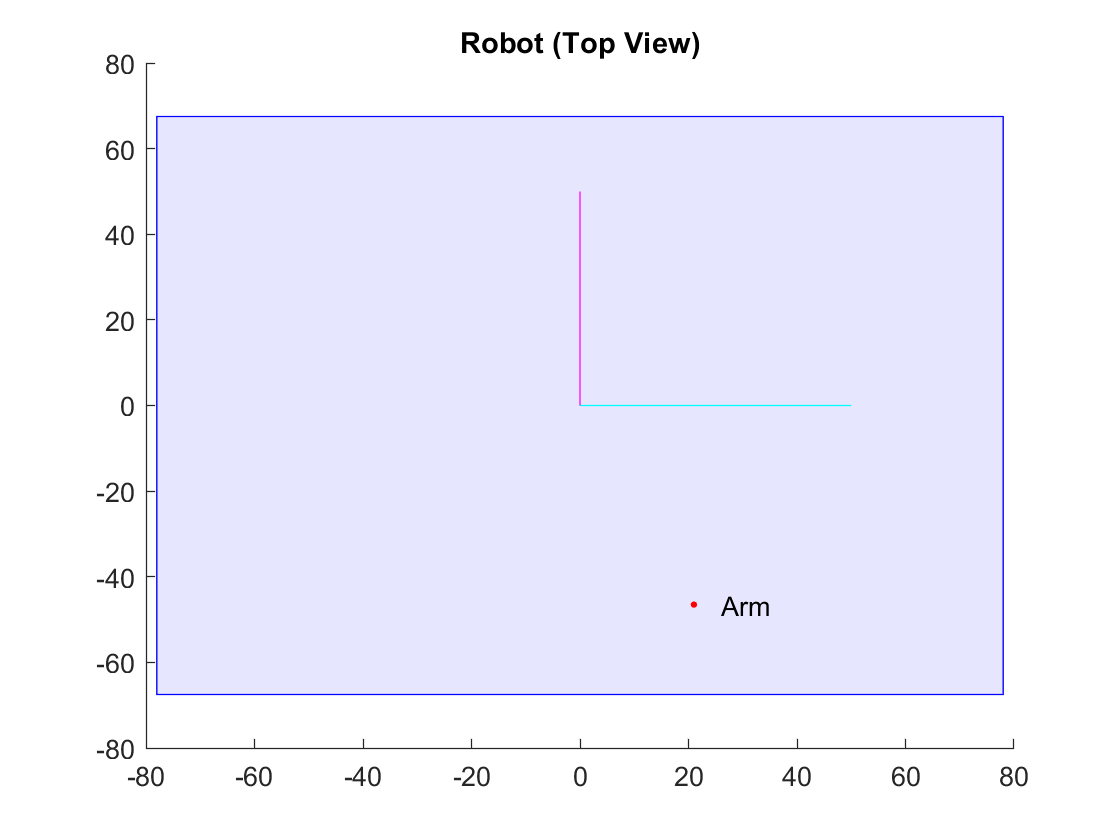

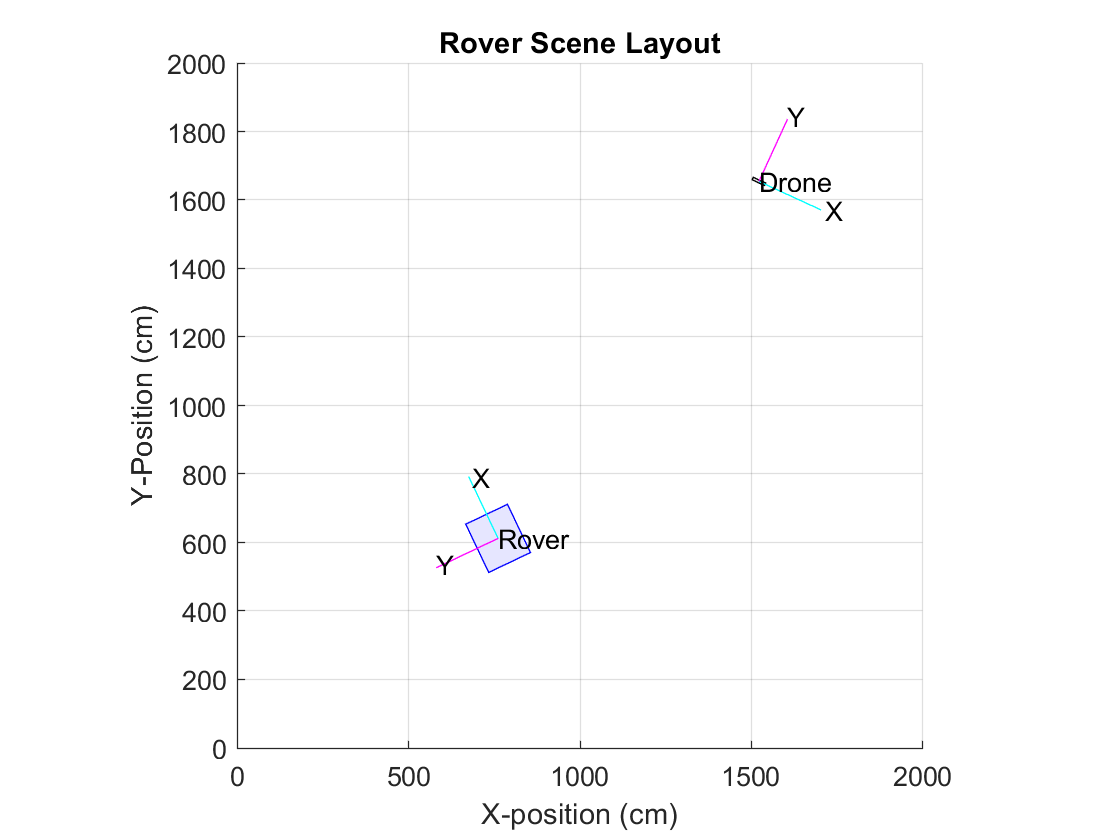

rover_info = struct with fields:
     length: 156
      width: 135
     height: 76
    arm_pos: [2×1 double]


rover_scene = struct with fields:
    rover_heading: 2.01510158961111
      rover_pitch: -0.139626340159546
       rover_roll: 0.174532925199433
        rover_pos: [3×1 double]
        drone_pos: [3×1 double]
    drone_heading: 5.85317057063514


[rover_info,rover_scene] = generate_rover_scene

% NOTE: If you are ever faced with an impossible question, just call the
% generator function again. This will make you a new question. You should
% leave the original question info intact, and include a note to explain
% why it is impossible to solve. 
%
% [rover_info2,rover_scene2] = generate_rover_scene

You are tasked with designing a retrieval arm to allow a Mars rover to pick up it's partner drone from the Martian surface and place it on the top surface of the rover for recharging. The overall dimensions of the rover are provided in the `rover_info` structure (distances are in cm and angles in radians). 

- Assume that the rover is a rectangular prism with specified length, width and height. 

- The axes of the body frame, $B$, are fixed to the rover. The $B_{x}$ direction is the nominal direction of travel and $B_{z}$ points 'up'. The origin lies at the geometric centre of the rover 'box'.

- You are tasked with designing a three-joint *positioning* part of the arm. 

- You must be able reach to the planetary surface in some neighbourhood of the rover. You must also be able to reach any point on the top surface of the rover. 

- The arm will eventually be equipped with an articulated gripper that will orient itself to grasp the drone, so you need not worry about the orientation of the end-effector, just its position. 

- The arm must be attached to a fixed point on the top surface of the rover. This mounting location is specified by an $x$ and $y$ value.  You *may *mount the arm above the top surface of the rover, but you should indicate why you have done so. The orientation of the arm frame can be chosen by the designer.

### Question 1:  (10 Marks)

Give a sketch of your arm, showing the joint arrangements and its approximate work area.  Identify the base reference frame for the arm and give the homogeneous transform back to the rover body-frame, i.e., $\mathbf{T}_{B0}$. Give a brief justification of your overall design choices (a few short paragraphs would be fine). 

*Notes*

- *You do not have to give detailed drawings of the joints, but you should identify any fixed joint offsets and fixed joint links. *

- *You do not have analyze  any aspects of the structural design (bending, etc.), *but you may comment on these factors in the description of your design.

- *The design does not have to be optimized but it should be sized appropriately to operate around the bed area without contacting walls, floors, ceiling, etc.*

#### Solution

Put your solution here

### Question 2:  (10 Marks)

Do a PoE analysis on your arm. Provide a table of the screw parameters, give all the component joint transforms, and the forward kinematic transform for whole manipulator. Write this final transform as $\mathbf{T}_{03}$

#### Solution

Put your solution here

### Question 3:  (10 Marks)

In one of your operations planning scenarios, you arrived at the scene shown in the second figure. This shows the placement and orientation of the rover and drone The exact details of the scene are provided in the `rover_scene` structure.

- The drone and robot positions are given in world coordinates (i.e,. with respect to Frame-$W$)

- The rover orientation is given by: $
\mathbf{C}_{WB}=\mathbf{R}_{z}\left(rover\_heading\right)\mathbf{R}_{y}\left(pitch\right)\mathbf{R}_{x}\left(roll\right)
$

- The drone orientation is given by: $
\mathbf{C}_{WD}=\mathbf{R}_{z}\left(drone\_heading\right)$

Find the relative pose $\mathbf{T}_{0D}$ between the robot arm and the drone (Note: do not worry if the drone is currently out of reach of the arm, the rover can drive over, after all). Note: You should not need to use the `inv` function for this question and full marks are only possible if you avoid its use.

#### Solution

Put your solution here

### Question 4: (5 Marks)

In another planning scenario you have positioned the rover and the arm appropriately and you must orient the wrist to make the final grasp. The kinematics of the wrist are given by a known set of Euler angles. The following variables show the Euler angle set for the wrist and the orientation matrix, $\mathbf{C}_{3D}$. 

[ea_order, C_3D] = rand_euler_angle

ea_order =      2     1     2


C_3D =          0.935679599817104        -0.352390076488447       -0.0180255507147603
         0.225778154931773         0.637188655907145        -0.736895407462179
         0.271160305431507         0.685428224379266         0.675766407853024


Solve for the three Euler angles ($\alpha$, $\beta$, and $\gamma $) corresponding the the orientation specified by $\mathbf{C}_{3D}$. 